filename = "lessonlearned.csv";
data = readtable(filename,'TextType','string');
head(data)

ans = 8×6 table
       Time       event_id                event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                abstract                                                                                                                                                                                                                                                                                                                                                        

idxEmpty = strlength(data.event_narrative) == 0;
data(idxEmpty,:) = [];
idxEmpty2 = strlength(data.abstract) == 0;
data(idxEmpty2,:) = [];

data.event_type = categorical(data.event_type);
data.safety = categorical(data.safety);

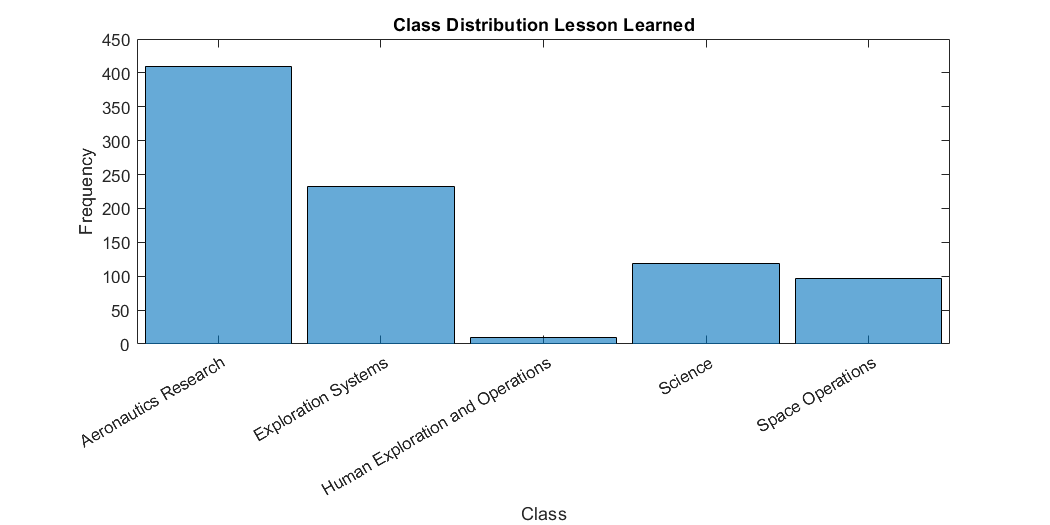

f = figure;
f.Position(3) = 1.5*f.Position(3);

h = histogram(data.event_type);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution Lesson Learned")

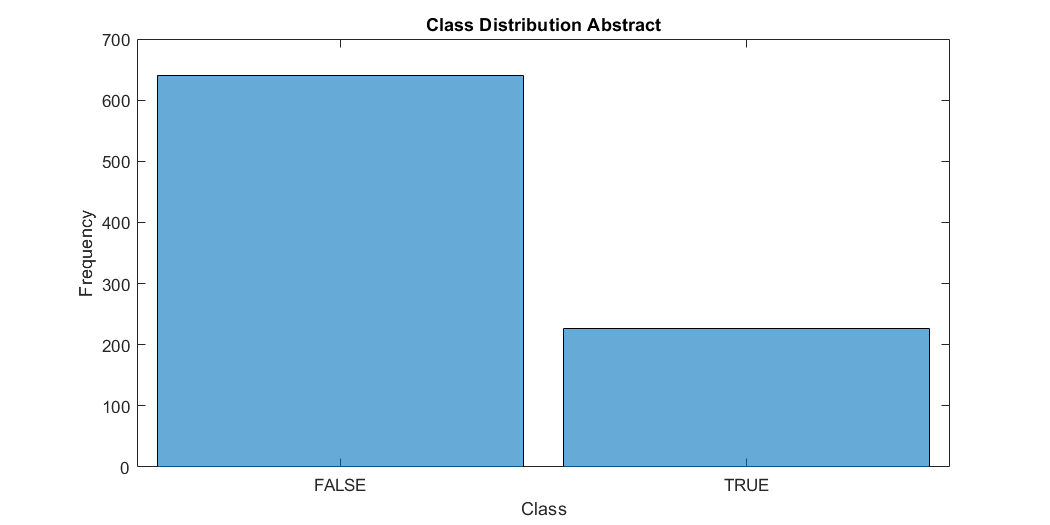

f2 = figure;
f2.Position(3) = 1.5*f2.Position(3);

h2 = histogram(data.safety);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution Abstract")

classCounts = h.BinCounts;
classNames = h.Categories;

classCounts2 = h2.BinCounts;
classNames2 = h2.Categories;

idxLowCounts = classCounts < 10;
infrequentClasses = classNames(idxLowCounts)

infrequentClasses = 1×1 cell array
    {'Human Exploration and Operations'}


idxLowCounts2 = classCounts2 < 10;
infrequentClasses2 = classNames2(idxLowCounts2)


infrequentClasses2 =

  1×0 empty cell array



idxInfrequent = ismember(data.event_type,infrequentClasses);
data(idxInfrequent,:) = [];
data.event_type = removecats(data.event_type);

idxInfrequent2 = ismember(data.safety,infrequentClasses2);
data(idxInfrequent2,:) = [];
data.safety = removecats(data.safety);

cvp = cvpartition(data.event_type,'Holdout',0.3);
dataTrain = data(training(cvp),:);
dataHeldOut = data(test(cvp),:);

cvp2 = cvpartition(data.safety,'Holdout',0.3);
dataTrain2 = data(training(cvp2),:);
dataHeldOut2 = data(test(cvp2),:);

cvp = cvpartition(dataHeldOut.event_type,'HoldOut',0.5);
dataValidation = dataHeldOut(training(cvp),:);
dataTest = dataHeldOut(test(cvp),:);

cvp2 = cvpartition(dataHeldOut2.safety,'HoldOut',0.5);
dataValidation2 = dataHeldOut2(training(cvp2),:);
dataTest2 = dataHeldOut2(test(cvp2),:);

textDataTrain = dataTrain.event_narrative;
textDataValidation = dataValidation.event_narrative;
textDataTest = dataTest.event_narrative;
YTrain = dataTrain.event_type;
YValidation = dataValidation.event_type;
YTest = dataTest.event_type;

textDataTrain2 = dataTrain2.abstract;
textDataValidation2 = dataValidation2.abstract;
textDataTest2 = dataTest2.abstract;
YTrain2 = dataTrain2.safety;
YValidation2 = dataValidation2.safety;
YTest2 = dataTest2.safety;

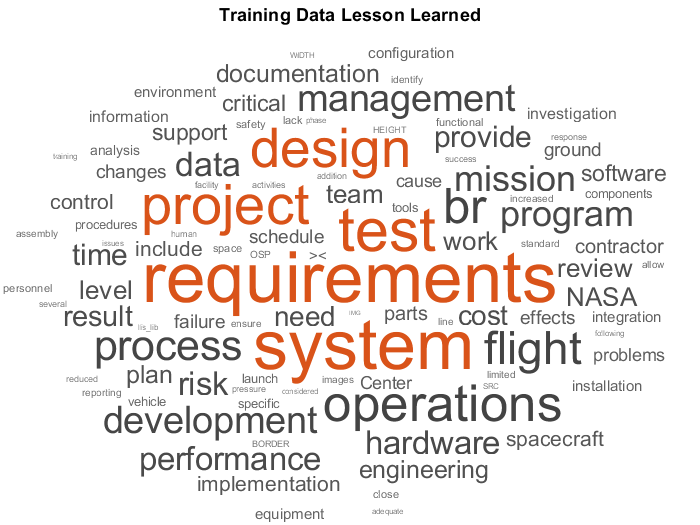

figure
wordcloud(textDataTrain);
title("Training Data Lesson Learned")

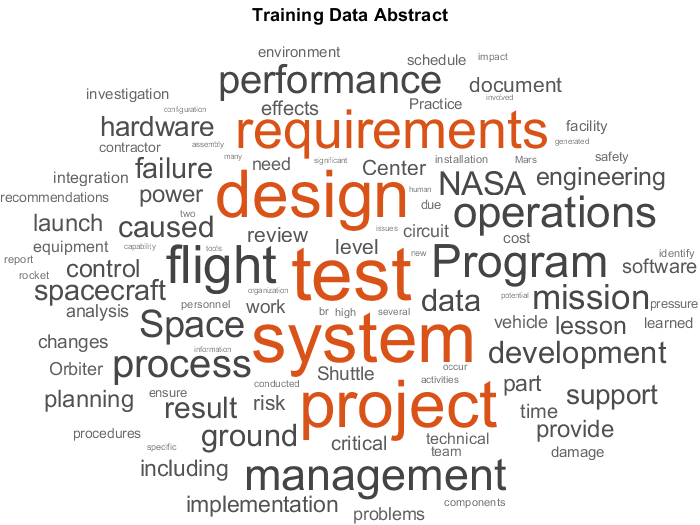

figure
wordcloud(textDataTrain2);
title("Training Data Abstract")

documentsTrain = preprocessText(textDataTrain);
documentsValidation = preprocessText(textDataValidation)

documentsValidation =   129×1 tokenizedDocument:

      83 tokens: simulated science data is needed by multiple groups within a project team to test their respective sdps elements even though the specific needs of each group may vary a cooperative effort among the different groups may reduce the amount of time required to generate an adequately complete set of simulated data for system test if the project fails to plan the timely generation of a complete set of simulated data system testing may be unable to verify and validate all critical operational modes
     213 tokens: providing paper or electronic copies of presentation materials to reviewers prior to the kickoff or board meetings would allow people to have better access to the material during meetings reviewers may have difficulty seeing the presentation some reviewers want to read the presentation prior to the meeting identifying the standing review board

documentsTrain2 = preprocessText(textDataTrain2);
documentsValidation2 = preprocessText(textDataValidation2)

documentsValidation2 =   129×1 tokenizedDocument:

     72 tokens: the jpl focus on primarily oneofakind flight systems and missions may result in insufficient priority placed on design documentation and missioncentric knowledge retention the oco2 project found the inherited orbiting carbon observatory design to be poorly documented assure that the spaceflight project retains the design knowledge needed to duplicate a system design train employees at all levels to recognize the value of projectgenerated knowledge and to champion its retention sharing and reuse
    165 tokens: 2010 was a significant year for nasaês james webb space telescope program the national academy of sciences astronomy decadal survey reaffirmed that completing the webb telescope was the nationês top astronomy priority at nearly the same time senator barbara mikulski a longtime webb advocate requested an independent review of the successor to

documentsTrain(1:5)

ans =   5×1 tokenizedDocument:

    195 tokens: laboratory testing revealed higher than anticipated safety risks from a potential arcflash event in a manhole environment when conducted at kscês unreduced fault current levels ¾ the safety risks included bright flash excessive sound and smoke ¾ ¾ due to these findings and absence of other mitigations installed at the time manhole entries require full arcflash ppe ¾ furthermore manhole entries were temporarily restricted to short duration inspections until further mitigations could be implemented ¾ with installation of neutral grounding resistors ngrs on substation transformers the flash sound and flame energy was reduced ¾ the hazard reduction was so substantial that the required ppe would be less cumbersome and enable effective performance of maintenance tasks in the energized configuration ¾ with the ngr installed the surge arresters currently used at ksc are not

documentsTrain2(1:5)

ans =   5×1 tokenizedDocument:

    146 tokens: power system distribution at kennedy space center ksc consists primarily of highvoltage underground cables these cables include approximately 5000 splices ¾ splice failures result in arc flash events that are extremely hazardous to personnel in the vicinity of the arc flash some construction and maintenance tasks cannot be performed effectively in the required personal protective equipment ppe and deenergizing the cables is not feasible due to cost lost productivity and safety risk to others implementing the required outages to verify alternate and effective mitigations arc flash testing was conducted in a controlled environment the arc flash effects were greater than expected testing also demonstrated the addition of neutral grounding resistors ngrs would result in substantial reductions to arc flash effects as a result ngrs are being installed on ksc primary subst

enc = wordEncoding(documentsTrain);
enc2 = wordEncoding(documentsTrain2);

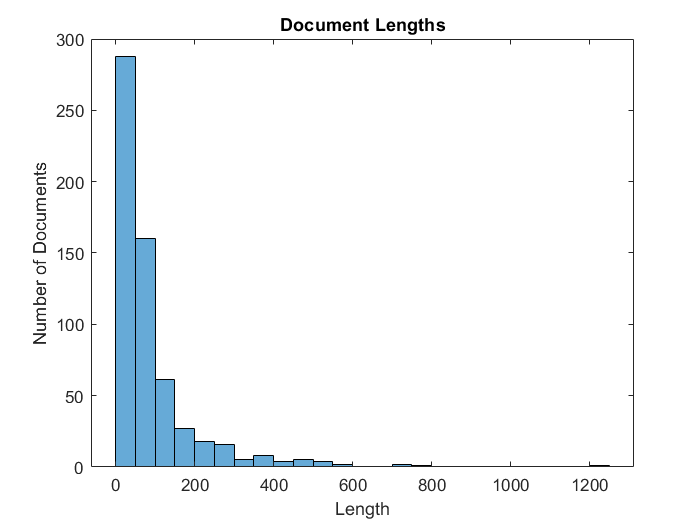

documentLengths = doclength(documentsTrain);
figure
histogram(documentLengths)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")

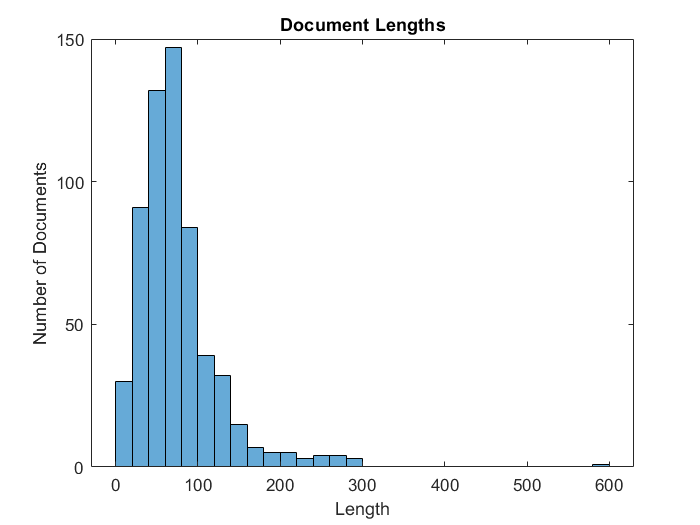

documentLengths2 = doclength(documentsTrain2);
figure
histogram(documentLengths2)
title("Document Lengths")
xlabel("Length")
ylabel("Number of Documents")

XTrain = doc2sequence(enc,documentsTrain,'Length',75);
XTrain(1:5)

ans = 5×1 cell array
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}


XTrain2 = doc2sequence(enc2,documentsTrain2,'Length',75);
XTrain2(1:5)

ans = 5×1 cell array
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}


XValidation = doc2sequence(enc,documentsValidation,'Length',75);
XValidation2 = doc2sequence(enc2,documentsValidation2,'Length',75);

inputSize = 1;
embeddingDimension = 100;
numWords = enc.NumWords;
numHiddenUnits = 180;
numClasses = numel(categories(YTrain));

layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   6x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 100 dimensions and 6622 unique words
     3   ''   LSTM                    LSTM with 180 hidden units
     4   ''   Fully Connected         4 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

inputSize2 = 1;
embeddingDimension2 = 100;
numWords2 = enc2.NumWords;
numHiddenUnits2 = 180;
numClasses2 = numel(categories(YTrain2));

layers2 = [ ...
    sequenceInputLayer(inputSize2)
    wordEmbeddingLayer(embeddingDimension2,numWords2)
    lstmLayer(numHiddenUnits2,'OutputMode','last')
    fullyConnectedLayer(numClasses2)
    softmaxLayer
    classificationLayer]

layers2 =   6x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 100 dimensions and 5990 unique words
     3   ''   LSTM                    LSTM with 180 hidden units
     4   ''   Fully Connected         2 fully connected layer
     5   ''   Softmax                 softmax
     6   ''   Classification Output   crossentropyex

options = trainingOptions('adam', ...
    'MaxEpochs',10, ...    
    'GradientThreshold',1, ...
    'InitialLearnRate',0.01, ...
    'ValidationData',{XValidation,YValidation}, ...
    'Plots','training-progress', ...
    'Verbose',false);

options2 = trainingOptions('adam', ...
    'MaxEpochs',10, ...    
    'GradientThreshold',1, ...
    'InitialLearnRate',0.01, ...
    'ValidationData',{XValidation2,YValidation2}, ...
    'Plots','training-progress', ...
    'Verbose',false);




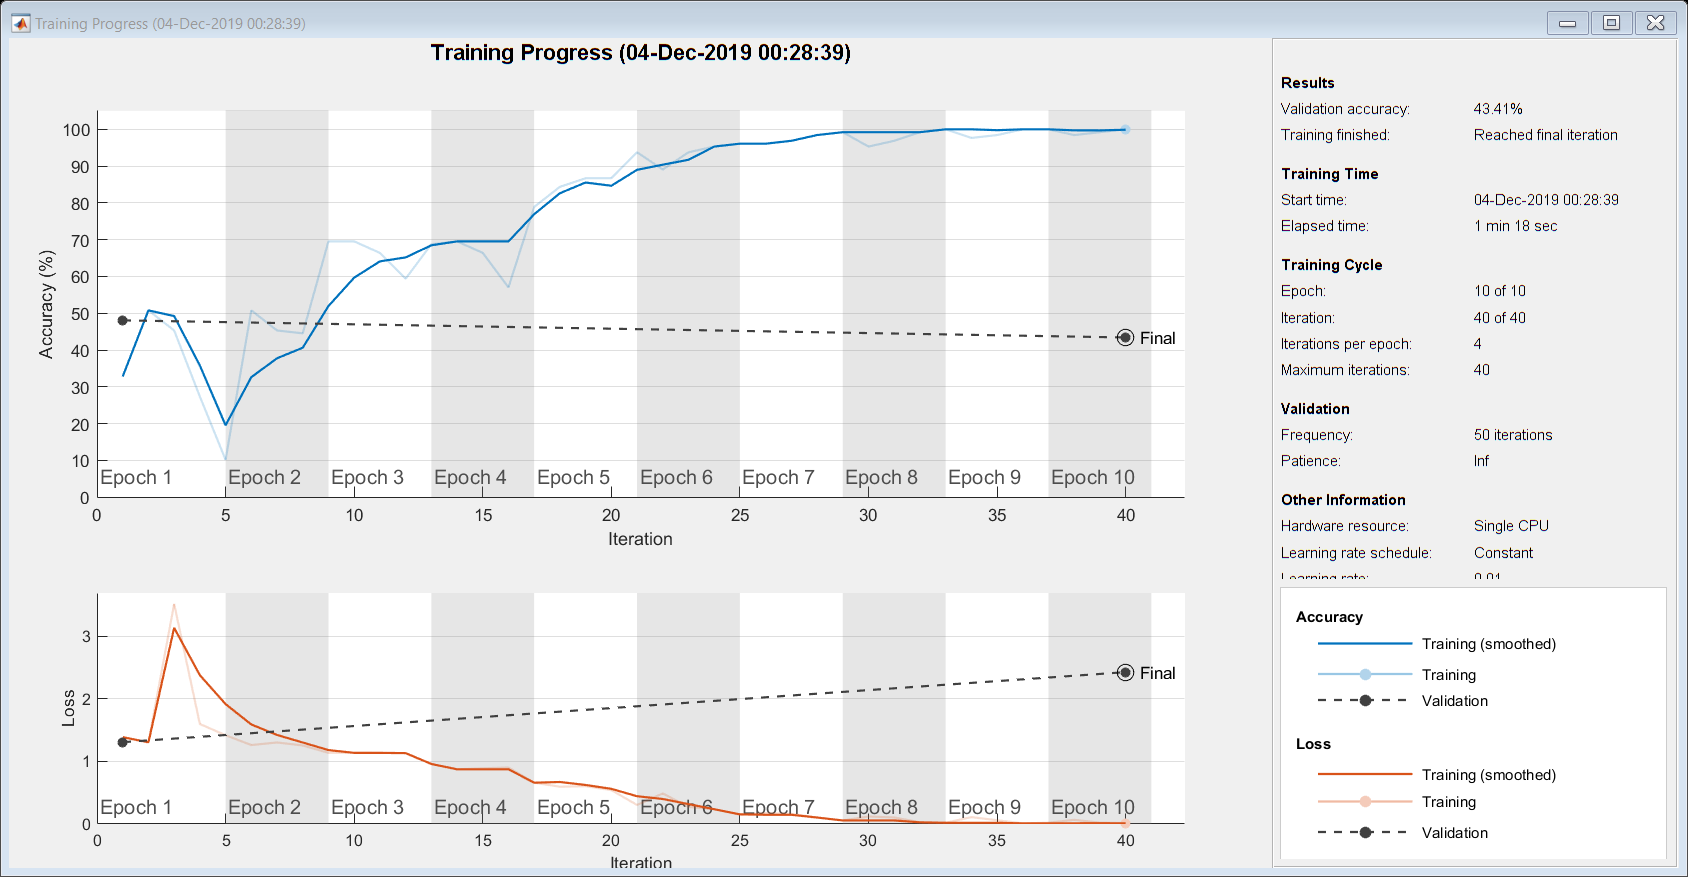

net = trainNetwork(XTrain,YTrain,layers,options);

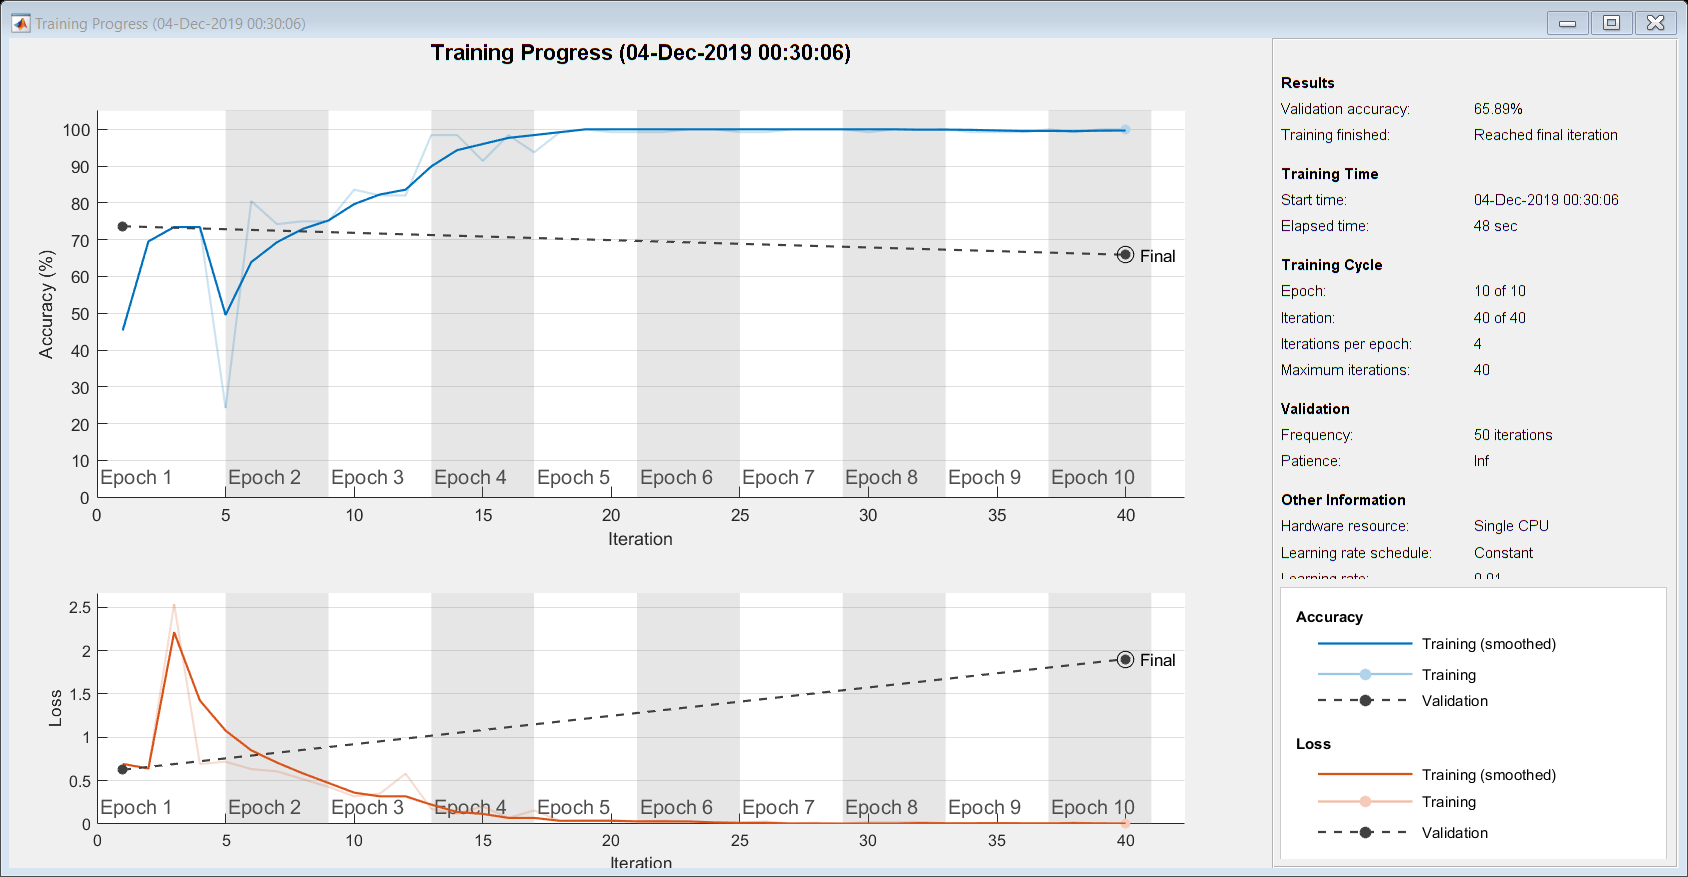

net2 = trainNetwork(XTrain2,YTrain2,layers2,options2);

textDataTest = lower(textDataTest);
documentsTest = tokenizedDocument(textDataTest);
documentsTest = erasePunctuation(documentsTest);

textDataTest2 = lower(textDataTest2);
documentsTest2 = tokenizedDocument(textDataTest2);
documentsTest2 = erasePunctuation(documentsTest2);

XTest = doc2sequence(enc,documentsTest,'Length',75);
XTest(1:5)

ans = 5×1 cell array
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}


XTest2 = doc2sequence(enc2,documentsTest2,'Length',75);
XTest2(1:5)

ans = 5×1 cell array
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}
    {1×75 double}


YPred = classify(net,XTest);
YPred2 = classify(net2,XTest2);

accuracy = sum(YPred == YTest)/numel(YPred)

accuracy = 0.4766

accuracy2 = sum(YPred2 == YTest2)/numel(YPred2)

accuracy2 = 0.6953

reportsNew = [ ...
    "NASA is better served by including certain baseline information, data, and (at least temporary) access to the model (or model-system) as required deliverables for analysis contracts. This additional information, data, or products can provide a more concrete basis for understanding the model, its development, and use."
    "NASA policy (NPR 7120.5 and NPR 7123.1B) and guidance (NASA Systems Engineering Handbook (SP-2016-6105), Rev 2) are primarily based on the waterfall development model. Programs using the lifecycle models described in these references must be aware the providers using a different life cycle model will not conform to the NASA waterfall model. This can lead to a variety of unfulfilled expectations and design activities that happen in a different sequence and time phasing than expected by the NASA model."
    "equirements should be managed in a single tool rather than allowing projects to have a separate way of managing their requirements. Evidence of design compliance (requirements verification matrices) should also be integrated into the tool to ensure all requirements are in sync and closure evidence is available. An alternative solution is to allow the use of different tools but to ensure that these data sets remain in sync (interoperability)."];

reportsNew2 = [ ...
    "NASA, on certain occasions, contracts for the accomplishment of M&S-based analyses with few requirements, if any, for delivery of the M&S or other development or use artifacts along with the results from the analyses.  While the costs for such contracts are lower, this practice provides an environment for potentially limiting the full and complete understanding of the model and data upon which the analyses are accomplished."
    "The Exploration Ground Systems (EGS) Program at Kennedy Space Center (KSC) experienced issues in the early phases of testing of Ground Support Equipment and other facility and support systems. These issues were related to: 1. test team having common understanding of individual roles and responsibilities; 2. Communicating problems and test status; 3. Processes used to integrate and coordinate work spanning multiple organizations; and 4. quickly dispositioning and resolving issues and returning to testing. The results of these issues included testing delays and cost growth. When performing large-scale complex testing it is important to ensure that equipment and supporting services are available before testing is initiated, roles and responsibilities are clearly understood, that the right stakeholders are involved in technical discussions and decisions, that problem resolutions and other technical decisions are made quickly and communicated clearly and that the process supports quickly returning to testing."
    "The Exploration Ground Systems Program received inputs (Review Item Discrepancies [RIDs], Requests for Action [RFAs]) and Action Items during the Critical Design Review (CDR) Life Cycle Review (LCR). Some of the RIDs and RFAs were submitted prior to and during the CDR and some inputs (such as RFAs or action items) resulted from follow-on out-briefings at higher levels in the Agency. RIDs, RFAs and action items were worked and closed with decision makers at various boards at the Program, cross-program or Agency level as appropriate. It was difficult and time-consuming to provide status information and closure evidence for all RIDs, RFAs and action items associated with the entire CDR life cycle review. This difficulty was due to the many sources of RIDs/RFAs and action items, the variety of forums at which these occurred and the period of time elapsed between close-out of the CDR and the final out-briefs at the Agency level."];

documentsNew = preprocessText(reportsNew);
documentsNew2 = preprocessText(reportsNew2);

XNew = doc2sequence(enc,documentsNew,'Length',75);
XNew2 = doc2sequence(enc,documentsNew2,'Length',75);

[labelsNew,score] = classify(net,XNew);
[labelsNew2,score2] = classify(net2,XNew2);

[reportsNew string(labelsNew)]

ans = 3×2 string array
    "NASA is better served by including certain baseline information, data, and (at least temporary) access to the model (or model-system) as required deliverables for analysis contracts. This additional information, data, or products can provide a more concrete basis for understanding the model, its development, and use."                                                                                                                                                                                               "Aeronautics Research"
    "NASA policy (NPR 7120.5 and NPR 7123.1B) and guidance (NASA Systems Engineering Handbook (SP-2016-6105), Rev 2) are primarily based on the waterfall development model. Programs using the lifecycle models described in these references must be aware the providers using a different life cycle model will not conform to the NASA waterfall model. This can lead to a variety of unfulfilled expectations and design activities that happen in

[reportsNew2 string(labelsNew2)]

ans = 3×2 string array
    "NASA, on certain occasions, contracts for the accomplishment of M&S-based analyses with few requirements, if any, for delivery of the M&S or other development or use artifacts along with the results from the analyses.  While the costs for such contracts are lower, this practice provides an environment for potentially limiting the full and complete understanding of the model and data upon which the analyses are accomplished."                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                

function documents = preprocessText(textData)

% Tokenize the text.
documents = tokenizedDocument(textData);

% Convert to lowercase.
documents = lower(documents);

% Erase punctuation.
documents = erasePunctuation(documents);

end